% open 5 csv files
first_fit_csv = fopen('First_Fit.csv');
random_fit_csv = fopen('Random_Fit.csv');
nsgaii_csv = fopen('NSGAII.csv');
haga_csv = fopen('HAGA.csv');
mcasga_csv = fopen('MCASGA.csv');

% read 5 csv files
first_fit = textscan(first_fit_csv, '%d%d%f%f%f%f%f%f%f%f%f%f', 'Delimiter', ',', 'HeaderLines', 1);
fclose(first_fit_csv);
random_fit = textscan(random_fit_csv, '%d%d%f%f%f%f%f%f%f%f%f%f', 'Delimiter', ',', 'HeaderLines', 1);
fclose(random_fit_csv);
nsgaii = textscan(nsgaii_csv, '%d%d%f%f%f%f%f%f%f%f%f%f', 'Delimiter', ',', 'HeaderLines', 1);
fclose(nsgaii_csv);
haga = textscan(haga_csv, '%d%d%f%f%f%f%f%f%f%f%f%f', 'Delimiter', ',', 'HeaderLines', 1);
fclose(haga_csv);
mcasga = textscan(mcasga_csv, '%d%d%d%f%f%f%f%f%f%f%f%f%f', 'Delimiter', ',', 'HeaderLines', 1);
fclose(mcasga_csv);

% extract data
app_num = deal(first_fit{1});
new_app_num = deal(first_fit{2});
time = deal(first_fit{3});

x_ticks = time;
n = length(time);
x_labels = {}


x_labels =

  0×0 empty cell array



for i = 1:1:n
    x_labels{i} = sprintf("%ds, %d apps", x_ticks(i), new_app_num(i))
end

x_labels = 1×1 cell array
    {["0s, 7 apps"]}


x_labels = 1×2 cell array
    {["0s, 7 apps"]}    {["29s, 12 apps"]}


x_labels = 1×3 cell array
    {["0s, 7 apps"]}    {["29s, 12 apps"]}    {["40s, 4 apps"]}


x_labels = 1×4 cell array
    {["0s, 7 apps"]}    {["29s, 12 apps"]}    {["40s, 4 apps"]}    {["41s, 4 apps"]}


x_labels = 1×5 cell array
    {["0s, 7 apps"]}    {["29s, 12 apps"]}    {["40s, 4 apps"]}    {["41s, 4 apps"]}    {["60s, 9 apps"]}


x_labels = 1×6 cell array
    {["0s, 7 apps"]}    {["29s, 12 apps"]}    {["40s, 4 apps"]}    {["41s, 4 apps"]}    {["60s, 9 apps"]}    {["65s, 8 apps"]}


x_labels = 1×7 cell array
    {["0s, 7 apps"]}    {["29s, 12 apps"]}    {["40s, 4 apps"]}    {["41s, 4 apps"]}    {["60s, 9 apps"]}    {["65s, 8 apps"]}    {["70s, 6 apps"]}


x_labels = 1×8 cell array
    {["0s, 7 apps"]}    {["29s, 12 apps"]}    {["40s, 4 apps"]}    {["41s, 4 apps"]}    {["60s, 9 apps"]}    {["65s, 8 apps"]}    {["70s, 6 apps"]}    {["165s, 13 apps"]}


x_labels = 1×9 cell array
    {["0s, 7 apps"]}    {["29s, 12 apps"]}    {["40s, 4 apps"]}    {["41s, 4 apps"]}    {["60s, 9 apps"]}    {["65s, 8 apps"]}    {["70s, 6 apps"]}    {["165s, 13 apps"]}    {["184s, 12 apps"]}


x_labels = 1×10 cell array
    {["0s, 7 apps"]}    {["29s, 12 apps"]}    {["40s, 4 apps"]}    {["41s, 4 apps"]}    {["60s, 9 apps"]}    {["65s, 8 apps"]}    {["70s, 6 apps"]}    {["165s, 13 apps"]}    {["184s, 12 apps"]}    {["191s, 10 apps"]}


x_labels = 1×11 cell array
    {["0s, 7 apps"]}    {["29s, 12 apps"]}    {["40s, 4 apps"]}    {["41s, 4 apps"]}    {["60s, 9 apps"]}    {["65s, 8 apps"]}    {["70s, 6 apps"]}    {["165s, 13 apps"]}    {["184s, 12 apps"]}    {["191s, 10 apps"]}    {["193s, 12 apps"]}


x_labels = 1×12 cell array
    {["0s, 7 apps"]}    {["29s, 12 apps"]}    {["40s, 4 apps"]}    {["41s, 4 apps"]}    {["60s, 9 apps"]}    {["65s, 8 apps"]}    {["70s, 6 apps"]}    {["165s, 13 apps"]}    {["184s, 12 apps"]}    {["191s, 10 apps"]}    {["193s, 12 apps"]}    {["207s, 8 apps"]}


x_labels = 1×13 cell array
    {["0s, 7 apps"]}    {["29s, 12 apps"]}    {["40s, 4 apps"]}    {["41s, 4 apps"]}    {["60s, 9 apps"]}    {["65s, 8 apps"]}    {["70s, 6 apps"]}    {["165s, 13 apps"]}    {["184s, 12 apps"]}    {["191s, 10 apps"]}    {["193s, 12 apps"]}    {["207s, 8 apps"]}    {["225s, 7 apps"]}


x_labels = 1×14 cell array
    {["0s, 7 apps"]}    {["29s, 12 apps"]}    {["40s, 4 apps"]}    {["41s, 4 apps"]}    {["60s, 9 apps"]}    {["65s, 8 apps"]}    {["70s, 6 apps"]}    {["165s, 13 apps"]}    {["184s, 12 apps"]}    {["191s, 10 apps"]}    {["193s, 12 apps"]}    {["207s, 8 apps"]}    {["225s, 7 apps"]}    {["236s, 6 apps"]}


x_labels = 1×15 cell array
    {["0s, 7 apps"]}    {["29s, 12 apps"]}    {["40s, 4 apps"]}    {["41s, 4 apps"]}    {["60s, 9 apps"]}    {["65s, 8 apps"]}    {["70s, 6 apps"]}    {["165s, 13 apps"]}    {["184s, 12 apps"]}    {["191s, 10 apps"]}    {["193s, 12 apps"]}    {["207s, 8 apps"]}    {["225s, 7 apps"]}    {["236s, 6 apps"]}    {["257s, 9 apps"]}


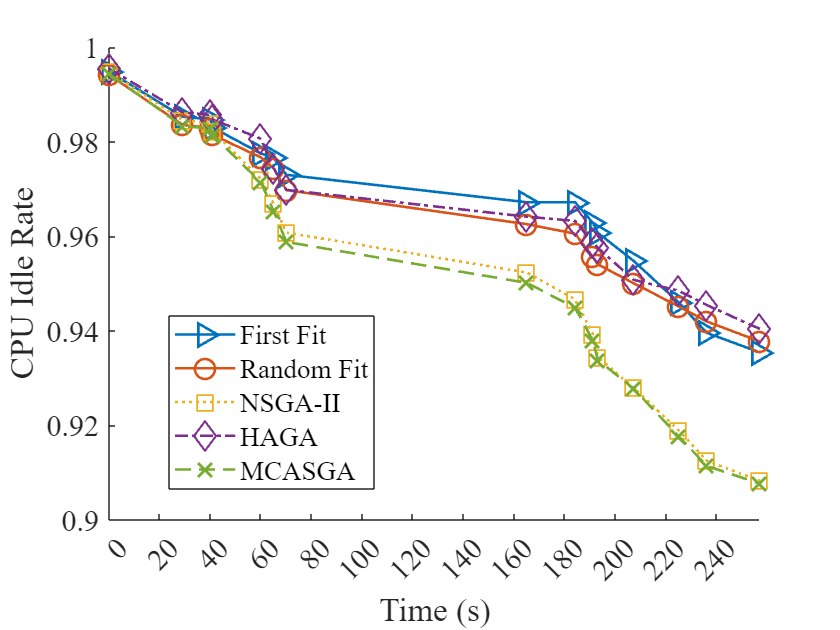



idx = 4;

first_fit_cpu = deal(first_fit{idx});
idx = idx+1;
first_fit_memory = deal(first_fit{idx});
idx = idx+1;
first_fit_storage = deal(first_fit{idx});
idx = idx+1;
first_fit_bandwidth = deal(first_fit{idx});
idx = idx+1;
first_fit_app_accept = deal(first_fit{idx});
idx = idx+1;
first_fit_svc_accept = deal(first_fit{idx});
idx = idx+1;
first_fit_task_accept = deal(first_fit{idx});
idx = idx+1;
first_fit_compl_t = deal(first_fit{idx});
idx = idx+1;
first_fit_compl_t_Pri = deal(first_fit{idx});

idx = 4;
random_fit_cpu = deal(random_fit{idx});
idx = idx+1;
random_fit_memory = deal(random_fit{idx});
idx = idx+1;
random_fit_storage = deal(random_fit{idx});
idx = idx+1;
random_fit_bandwidth = deal(random_fit{idx});
idx = idx+1;
random_fit_app_accept = deal(random_fit{idx});
idx = idx+1;
random_fit_svc_accept = deal(random_fit{idx});
idx = idx+1;
random_fit_task_accept = deal(random_fit{idx});
idx = idx+1;
random_fit_compl_t = deal(random_fit{idx});
idx = idx+1;
random_fit_compl_t_Pri = deal(random_fit{idx});

idx = 4;
nsgaii_cpu = deal(nsgaii{idx});
idx = idx+1;
nsgaii_memory = deal(nsgaii{idx});
idx = idx+1;
nsgaii_storage = deal(nsgaii{idx});
idx = idx+1;
nsgaii_bandwidth = deal(nsgaii{idx});
idx = idx+1;
nsgaii_app_accept = deal(nsgaii{idx});
idx = idx+1;
nsgaii_svc_accept = deal(nsgaii{idx});
idx = idx+1;
nsgaii_task_accept = deal(nsgaii{idx});
idx = idx+1;
nsgaii_compl_t = deal(nsgaii{idx});
idx = idx+1;
nsgaii_compl_t_Pri = deal(nsgaii{idx});

idx = 4;
haga_cpu = deal(haga{idx});
idx = idx+1;
haga_memory = deal(haga{idx});
idx = idx+1;
haga_storage = deal(haga{idx});
idx = idx+1;
haga_bandwidth = deal(haga{idx});
idx = idx+1;
haga_app_accept = deal(haga{idx});
idx = idx+1;
haga_svc_accept = deal(haga{idx});
idx = idx+1;
haga_task_accept = deal(haga{idx});
idx = idx+1;
haga_compl_t = deal(haga{idx});
idx = idx+1;
haga_compl_t_Pri = deal(haga{idx});

idx = 4;
mcasga_cpu = deal(mcasga{idx});
idx = idx+1;
mcasga_memory = deal(mcasga{idx});
idx = idx+1;
mcasga_storage = deal(mcasga{idx});
idx = idx+1;
mcasga_bandwidth = deal(mcasga{idx});
idx = idx+1;
mcasga_app_accept = deal(mcasga{idx});
idx = idx+1;
mcasga_svc_accept = deal(mcasga{idx});
idx = idx+1;
mcasga_task_accept = deal(mcasga{idx});
idx = idx+1;
mcasga_compl_t = deal(mcasga{idx});
idx = idx+1;
mcasga_compl_t_Pri = deal(mcasga{idx});


set(groot,'defaultLineMarkerSize',10);


plot(time, first_fit_cpu, '->', time, random_fit_cpu, '-o', time, nsgaii_cpu, ':square', time, haga_cpu, '-.diamond', time, mcasga_cpu, '--x', 'LineWidth', 1.3);
set(gca, 'Fontname', 'Times New Roman','FontSize',15);
legend('First Fit', 'Random Fit', 'NSGA-II', 'HAGA', 'MCASGA', 'Location','best');
xlabel('Time (s)');
ylabel('CPU Idle Rate');
% xticks(x_ticks);
% xticklabels(x_labels);
% annotation('textarrow', [0.5 0.6], [0.5 0.6], 'String', 'aaa');
xticks(0:20:time(end));
xlim tight
box off

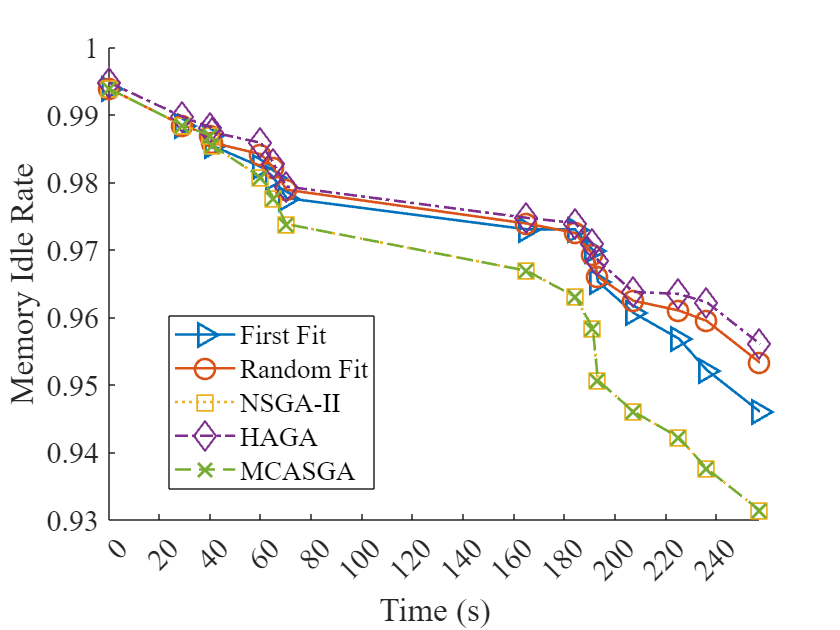


plot(time, first_fit_memory, '->', time, random_fit_memory, '-o', time, nsgaii_memory, ':square', time, haga_memory, '-.diamond', time, mcasga_memory, '--x', 'LineWidth', 1.3);
set(gca, 'Fontname', 'Times New Roman','FontSize',15);
legend('First Fit', 'Random Fit', 'NSGA-II', 'HAGA', 'MCASGA', 'Location','best');
xlabel('Time (s)');
ylabel('Memory Idle Rate');
% xticks(x_ticks);
% xticklabels(x_labels);
xticks(0:20:time(end));
xlim tight
box off

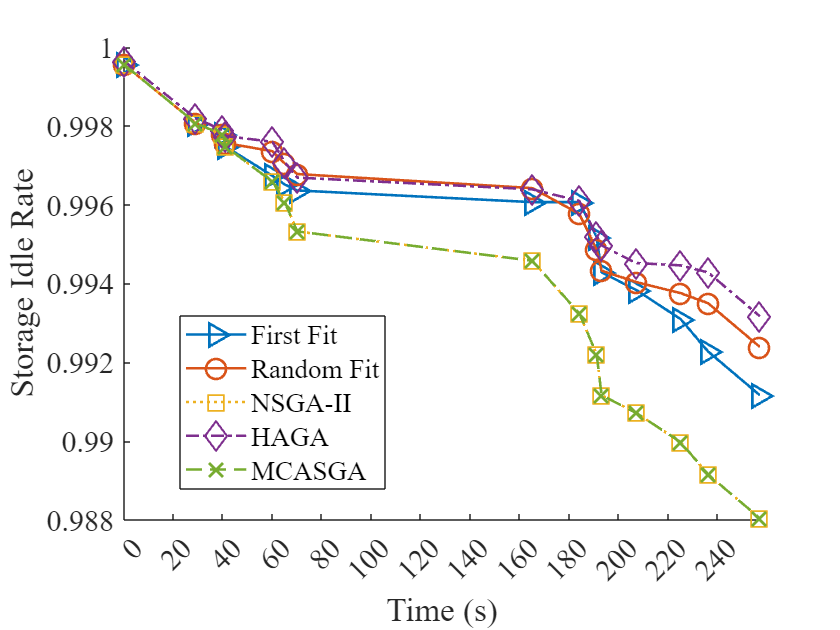


plot(time, first_fit_storage, '->', time, random_fit_storage, '-o', time, nsgaii_storage, ':square', time, haga_storage, '-.diamond', time, mcasga_storage, '--x', 'LineWidth', 1.3);
set(gca, 'Fontname', 'Times New Roman','FontSize',15);
legend('First Fit', 'Random Fit', 'NSGA-II', 'HAGA', 'MCASGA', 'Location','best');
xlabel('Time (s)');
ylabel('Storage Idle Rate');
% xticks(x_ticks);
% xticklabels(x_labels);
xticks(0:20:time(end));
xlim tight
box off

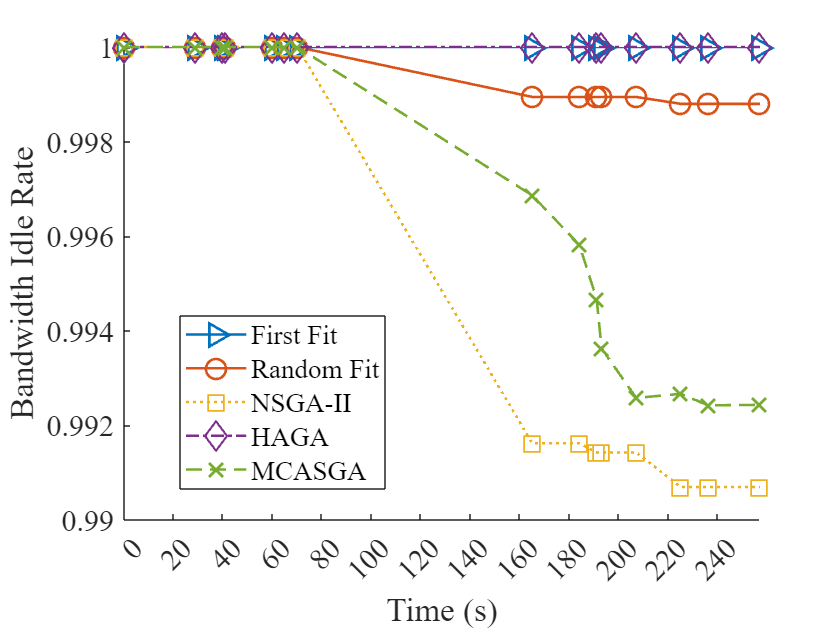


plot(time, first_fit_bandwidth, '->', time, random_fit_bandwidth, '-o', time, nsgaii_bandwidth, ':square', time, haga_bandwidth, '-.diamond', time, mcasga_bandwidth, '--x', 'LineWidth', 1.3);
set(gca, 'Fontname', 'Times New Roman','FontSize',15);
legend('First Fit', 'Random Fit', 'NSGA-II', 'HAGA', 'MCASGA', 'Location','best');
xlabel('Time (s)');
ylabel('Bandwidth Idle Rate');
% xticks(x_ticks);
% xticklabels(x_labels);
xticks(0:20:time(end));
xlim tight
box off

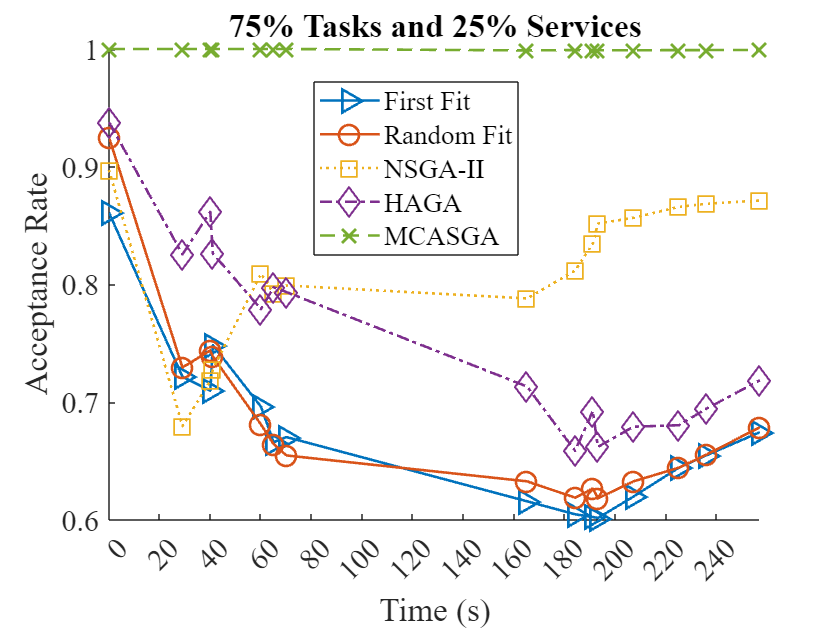


plot(time, first_fit_app_accept, '->', time, random_fit_app_accept, '-o', time, nsgaii_app_accept, ':square', time, haga_app_accept, '-.diamond', time, mcasga_app_accept, '--x', 'LineWidth', 1.3);
set(gca, 'Fontname', 'Times New Roman','FontSize',15);
legend('First Fit', 'Random Fit', 'NSGA-II', 'HAGA', 'MCASGA', 'Location','best');
xlabel('Time (s)');
ylabel('Acceptance Rate');
% xticks(x_ticks);
% xticklabels(x_labels);
xticks(0:20:time(end));
xlim tight
title('75% Tasks and 25% Services');
box off

plot(time, first_fit_svc_accept, '->', time, random_fit_svc_accept, '-o', time, nsgaii_svc_accept, ':square', time, haga_svc_accept, '-.diamond', time, mcasga_svc_accept, '--x', 'LineWidth', 1.3);

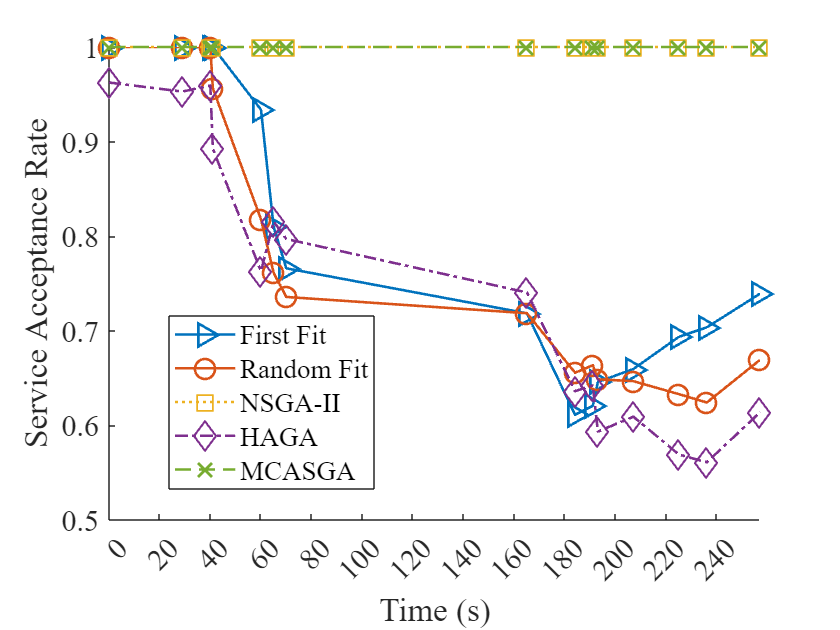

set(gca, 'Fontname', 'Times New Roman','FontSize',15);
legend('First Fit', 'Random Fit', 'NSGA-II', 'HAGA', 'MCASGA', 'Location','best');
xlabel('Time (s)');
ylabel('Service Acceptance Rate');
% xticks(x_ticks);
% xticklabels(x_labels);
xticks(0:20:time(end));
xlim tight
box off

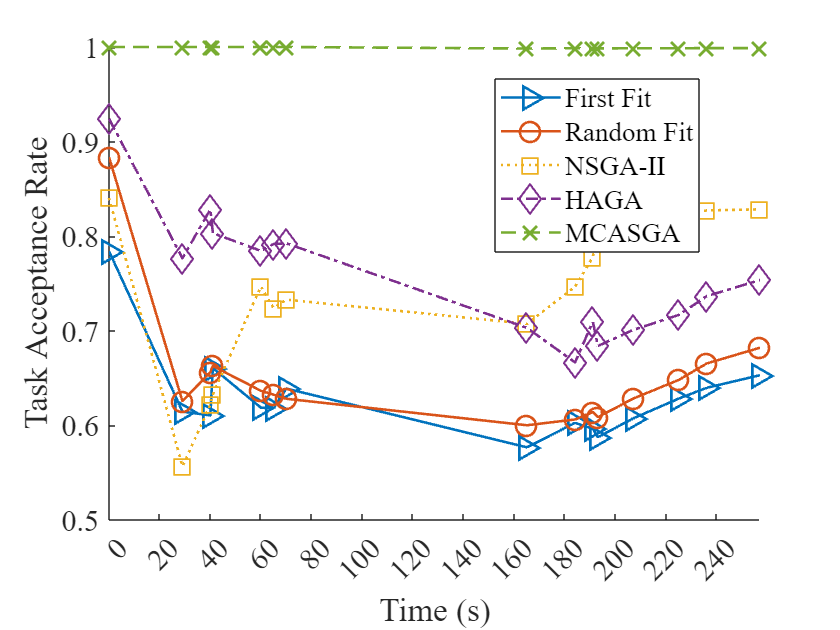


plot(time, first_fit_task_accept, '->', time, random_fit_task_accept, '-o', time, nsgaii_task_accept, ':square', time, haga_task_accept, '-.diamond', time, mcasga_task_accept, '--x', 'LineWidth', 1.3);
set(gca, 'Fontname', 'Times New Roman','FontSize',15);
legend('First Fit', 'Random Fit', 'NSGA-II', 'HAGA', 'MCASGA', 'Location','best');
xlabel('Time (s)');
ylabel('Task Acceptance Rate');
% xticks(x_ticks);
% xticklabels(x_labels);
xticks(0:20:time(end));
xlim tight
box off

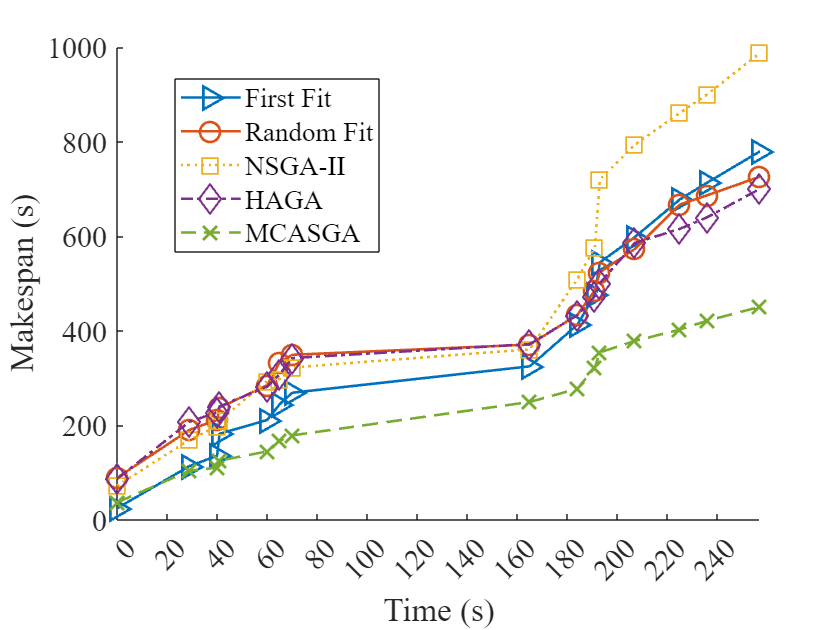


plot(time, first_fit_compl_t, '->', time, random_fit_compl_t, '-o', time, nsgaii_compl_t, ':square', time, haga_compl_t, '-.diamond', time, mcasga_compl_t, '--x', 'LineWidth', 1.3);
set(gca, 'Fontname', 'Times New Roman','FontSize',15);
legend('First Fit', 'Random Fit', 'NSGA-II', 'HAGA', 'MCASGA', 'Location','best');
xlabel('Time (s)');
ylabel('Makespan (s)');
% xticks(x_ticks);
% xticklabels(x_labels);
xticks(0:20:time(end));
xlim tight
box off

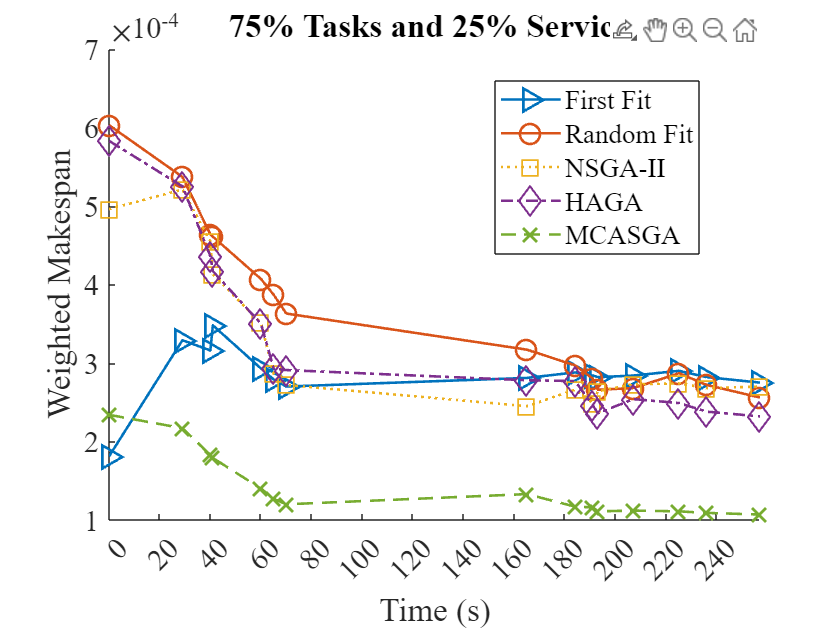


plot(time, first_fit_compl_t_Pri, '->', time, random_fit_compl_t_Pri, '-o', time, nsgaii_compl_t_Pri, ':square', time, haga_compl_t_Pri, '-.diamond', time, mcasga_compl_t_Pri, '--x', 'LineWidth', 1.3);
set(gca, 'Fontname', 'Times New Roman','FontSize',15);
legend('First Fit', 'Random Fit', 'NSGA-II', 'HAGA', 'MCASGA', 'Location','best');
xlabel('Time (s)');
ylabel('Weighted Makespan');
% xticks(x_ticks);
% xticklabels(x_labels);
xticks(0:20:time(end));
xlim tight
title('75% Tasks and 25% Services');
box off


%ax = gca;
%ax.YLim = [0.6, 1];




